## **Introduction **

This script replicates the main empirical findings from Frazzini and Pedersen (2014) regarding the beta anormaly. We will not cover everything in the article, but instead pay most attention to those aspects related to portfolio sorting. 

In replicating their empirical findings, we will rely on data from the both the daily and the monthly CRSP stock file using all common shares (*SHRCD *10 and 11) listed on the NYSE, AMEX, and NASDAQ exchanges (*EXCHCD *1, 2, and 3). As such, this script also provides a simple illustration of how to merge the two stock files. We first compute exposures to the market, using daily data and then sort stocks into deciles based on this measure. 

Beware that this is a substantially larger file compared to the CRPS monthly stock file, and will inevitably make scripts take longer to run. However, to facilite the process, I have provided you with pre-processed matfiles with the data. The script *makeDailyCRSP.m *illustrates how to process the raw data. The CRSP daily file for the period considered here is about 2.8GB.

Next, we examine whether demand for lottery stocks provides an explanation for the anormaly. We do this by constructing the MAX measure of Bali et. al (2017) and do a dependent bivariate sort.

The script ends with pointing out some critique points raised by Novy-Marx and Velikov (2022). 

## Data and estimation

We begin by loading the pre-processed daily CRSP stock file stored in the *crspDataDaily.mat* file. This file is created using the *makeDailyCRSP.m* script that takes the full daily stock file and eliminates stocks that does not conform to the requirements listed above and structures the data in matrix format. The file here contains data from January 1986 to December 2019.

% Housekeeping
clear;
clc;

% Loading CRSP daily stock data
load("crspDataDaily.mat");
ret_daily=ret;

% Log excess returns
logReturns=log(1+ret./100)-ff(:,end)./100; 
logMkt=log(1+ff(:,2)./100+ff(:,end)./100)-ff(:,end)./100;

nAssets     = size(exret,2);
T     = size(exret,1);
% estimating sigma and rho


### Estimating market exposures

In order to estimate the market exposure, we follow Frazzini and Pedersen (2014) and split the beta into two components a correlation and a fraction of volatilities. We estimate the correlation using 5 year rolling window of 3-day overlapping returns. Next, we estimate the volatilities using a 1 year rolling window. 

sigma=nan(T, nAssets); 
rho=nan(T, nAssets); 
beta=nan(T, nAssets); 
sigma_mkt=nan(T, nAssets); 

r_3d=movsum(logReturns,[3 0]); 
r_3d_mk=movsum(logMkt,[3 0]);

M1 = movmean(r_3d(:,:).*r_3d_mk(:,:),[1250, 0],'omitnan')-movmean(r_3d(:,:),[1250, 0],'omitnan').*movmean(r_3d_mk(:,:),[1250, 0],'omitnan');
M2 = sqrt(movvar(r_3d(:,:),[1250, 0],'omitnan'));
M3 = sqrt(movvar(r_3d_mk(:,:),[1250, 0],'omitnan'));

rho(1251:end,:)=M1(1251:end,:)./(M2(1251:end,:).*M3(1251:end,:));


sigma = movstd(logReturns,[250 0], 'omitnan'); 
sigma_mkt = movstd(logMkt,[250 0], 'omitnan');
sigma_mkt(1:1250,:)=nan(); 
sigma(1:1250,:)=nan(); 

nans=isnan(logReturns);
I=find((movsum(nans,[250 0])>120));
sigma(I)=nan(); 
nans=isnan(r_3d);
I=find((movsum(nans,[1250 0])>750));
rho(I)=nan(); 


beta=rho.*sigma./sigma_mkt; 

%adjust towards the true cross-sectional average
beta=0.6*beta+0.4*1; 
beta=[beta(month(vDates(2:end,:)) ~=month(vDates(1:end-1,:)),:);beta(end,:)]; 

vPermnoDaily = vPermno;

vDatesDaily = vDates;

% Loading CRSP monthly stock data
load("crspDataMonthly2.mat");

% Identifying overlap between monthly and daily stock file
[~,~,permIdx]   = intersect(vPermno,vPermnoDaily);

% Elimining stocks not in the monthly file
beta         = beta(:,permIdx);


### Building Beta portfolios 

We now sort our cross-section based on beta estimates. The long-short portfolio is constructed using the rank-based method of Frazzini and Pedersen (2014). In addition, we estimate CAPM, FF3, and FF5 alphas. 

load('ff5');
% Setting number of portfolios
numPort     = 10;

% Setting percentiles 
prctlVals   = 10:10:90;

bab10fac    = univariateSort(exret,beta,prctlVals,'EW'); 


[row, col] = find(~isnan(beta));

r=nan(size(beta)); 
for i=1:size(beta,1)
   r(i,:)=tiedrank(beta(i,:)); 
    
end




k=2./nansum(abs(r-nanmean(r,2)),2); 
%Low and high weights
w_h=k.*abs(r-nanmean(r,2)).*((r-nanmean(r,2))>0); 
w_l=k.*abs(r-nanmean(r,2)).*((r-nanmean(r,2))<=0); 

%low and high beates
beta_L=nansum(beta.*w_l,2); 
beta_H=nansum(beta.*w_h,2); 
beta_H(beta_H==0)=nan(); 
beta_L(beta_L==0)=nan();
%low and high returns
r_L=nansum(exret.*w_l,2); 
r_H=nansum(exret.*w_h,2); 

% Constructing the BAB factor
BAB_factor=1./beta_L.*r_L-1./beta_H.*r_H;

regResults = nwRegress([bab10fac.returns(61:end,:),BAB_factor(61:end,:)],ones(size(BAB_factor(61:end,:),1),1),0,6); 
table(1,:)=regResults.bv; 
table(2,:)=regResults.tbv; 
%CAPM alphas
regResults = nwRegress([bab10fac.returns(61:end,:),BAB_factor(61:end,:)],ff(61:end,2),1,6); 
table(3,:)=regResults.bv(1,:); 
table(4,:)=regResults.tbv(1,:); 

%FF3 alphas
regResults = nwRegress([bab10fac.returns(61:end,:),BAB_factor(61:end,:)],ff(61:end,2:4),1,6); 
table(5,:)=regResults.bv(1,:); 
table(6,:)=regResults.tbv(1,:); 

%FF5 alphas
regResults = nwRegress([bab10fac.returns(61:end,:),BAB_factor(61:end,:)],ff5(61:end,:),1,6); 
table(7,:)=regResults.bv(1,:); 
table(8,:)=regResults.tbv(1,:); 

%Sharpe ratios
table(9,:)=sqrt(12)*table(1,:)./nanstd([bab10fac.returns, BAB_factor(1:end,:)]); 


table

table =     1.0783    1.0104    1.1404    1.1419    1.1587    1.0698    1.1478    1.1134    1.1739    1.1521    0.8790
    4.2989    4.0544    4.5127    4.1901    4.0110    3.4927    3.4545    2.9254    2.5915    1.9086    3.6250
    0.7254    0.5675    0.6116    0.5188    0.4566    0.2798    0.2709    0.1207    0.0024   -0.3293    1.2452
    3.3538    2.8768    3.2341    2.7233    2.5478    1.4955    1.4701    0.5509    0.0094   -0.8654    4.7861
    0.6323    0.4555    0.5065    0.4044    0.3435    0.1651    0.1654    0.0290   -0.0540   -0.3770    1.1236
    3.7982    3.3326    4.2418    3.7706    3.4313    1.7798    1.6972    0.2399   -0.3338   -1.3898    5.4656
    0.6434    0.3811    0.4348    0.3247    0.2741    0.1563    0.2342    0.1775    0.2755    0.2035    0.7983
    3.6142    2.6451    3.4344    2.8206    2.5748    1.4780    1.8384    1.1139    1.3102    0.6805    3.7075
    1.1143    0.9933    1.0118    0.8977    0.8425    0.6937    0.6752    0.5608    0.4881    0.3596    

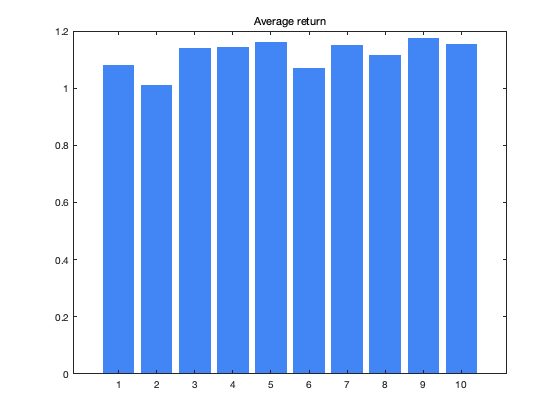


% Plotting the average returns
figure; 
b1 = bar(nanmean(bab10fac.returns));
b1.FaceColor = colorBrewer(1);
b1.EdgeColor = colorBrewer(1);
title('Average return','FontWeight','normal');

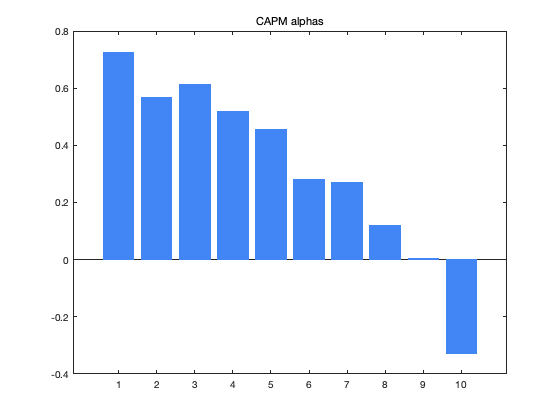


% Plotting the Alphas
figure; 
b1 = bar(table(3,1:10));
b1.FaceColor = colorBrewer(1);
b1.EdgeColor = colorBrewer(1);
title('CAPM alphas','FontWeight','normal');

## Lottery demand based as an explanation?

In the nexxt section we examine whether demand for lottery stocks can explain the beta anormaly. We calculate the MAX measure following Bali et. al (2017) by the average of the five highest returns in the previous month. We show that the average MAX value is highest for the high beta portfolio. To examine whether the lottery demand provides an explanation, we apply a dependent bivariate sort in which we first sort on MAX and afterwards the betas of Frazzini and Pedersen (2014).

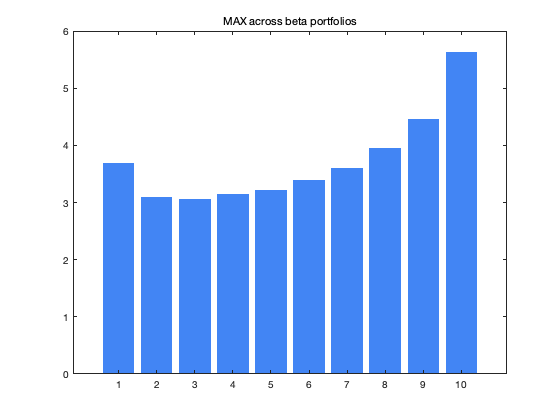




FMAX=nan(size(beta,1),size(ret_daily,2));

for i=1:size(beta,1)
    idx=find(month(vDatesDaily)==month(vDates(i)) & year(vDatesDaily)==year(vDates(i))); 
    
    FMAX(i,:)=mean(maxk(ret_daily(idx,:),5,1),1); 
    idx2=sum(~isnan(ret_daily(idx,:)));
    FMAX(i,idx2<15)=nan(); 
    
end

FMAX         = FMAX(:,permIdx);

% Show the average MAX value for the ten beta portfolios
for i=61:408
    for j=1:10
    MAX_beta(i,j)=nanmean(FMAX(i,bab10fac.placement(i,:)==j),2); 
    end
end
figure; 
b1 = bar(nanmean(MAX_beta));
b1.FaceColor = colorBrewer(1);
b1.EdgeColor = colorBrewer(1);
title('MAX across beta portfolios','FontWeight','normal');


% Univariate sort on MAX

Lottery10fac    = univariateSort(exret,FMAX,prctlVals,'EW');

regResults = nwRegress([Lottery10fac.returns(3:end,:)],ones(size(BAB_factor(3:end,:),1),1),0,6); 
table3(1,:)=regResults.bv; 
table3(2,:)=regResults.tbv; 

regResults = nwRegress([Lottery10fac.returns(3:end,:)],ff(3:end,2),1,6); 
table3(3,:)=regResults.bv(1,:); 
table3(4,:)=regResults.tbv(1,:); 

regResults = nwRegress([Lottery10fac.returns(3:end,:)],ff(3:end,2:4),1,6); 
table3(5,:)=regResults.bv(1,:); 
table3(6,:)=regResults.tbv(1,:); 

regResults = nwRegress([Lottery10fac.returns(3:end,:)],ff5(3:end,:),1,6); 
table3(7,:)=regResults.bv(1,:); 
table3(8,:)=regResults.tbv(1,:); 

table3

table3 =     0.8712    1.0333    1.0098    1.0061    0.9379    0.9017    0.7826    0.6587    0.4379    0.3166
    4.1905    4.7465    4.3284    3.9718    3.3903    2.9008    2.2893    1.7072    0.9817    0.5896
    0.4817    0.4920    0.3924    0.3318    0.2055    0.1126   -0.0668   -0.2356   -0.5065   -0.6299
    2.8719    3.2756    2.7582    2.2568    1.3496    0.7100   -0.3677   -1.0803   -1.9422   -1.7021
    0.4097    0.4120    0.3273    0.2809    0.1755    0.1202   -0.0226   -0.1522   -0.4060   -0.4980
    3.1907    4.3693    3.7807    3.4328    2.0986    1.4283   -0.2424   -1.1731   -2.4580   -1.8486
    0.3073    0.2912    0.2142    0.2329    0.1797    0.2085    0.1651    0.1339    0.0346    0.0901
    2.3932    3.3489    2.6563    2.6512    1.7826    1.9784    1.2671    0.7586    0.1782    0.3135



out = bivariateSort(exret,FMAX,beta,prctlVals,prctlVals,'Conditional','EW'); 

for i=1:10
    table4(i)=nanmean([out.returns(61:end,(i-1)*10+1)-out.returns(61:end,(i-1)*10+10)]); 
regResults = nwRegress([out.returns(61:end,(i-1)*10+1)-out.returns(61:end,(i-1)*10+10)],[ff5(61:end,:)],1,6); 
table4(1,i)=regResults.bv(1); 
table4(2,i)=regResults.tbv(1); 
end
table4

table4 =     0.0483   -0.3398   -0.2379   -0.0782   -0.2996    0.5670    0.4157    0.3411    0.2879    1.0259
    0.0350   -0.0826    0.0034   -0.1633    0.7026    1.6672    0.9571    0.7783    0.5059    1.5459


## The critique points of Novy-Marx and Velikov (2022)

We end the mlx file by exmaining some of the points raised by Novy-Marx and Velikov (2022). We start by studying the market-value of the beta portfolios and consider value weighted BAB factor instead. 

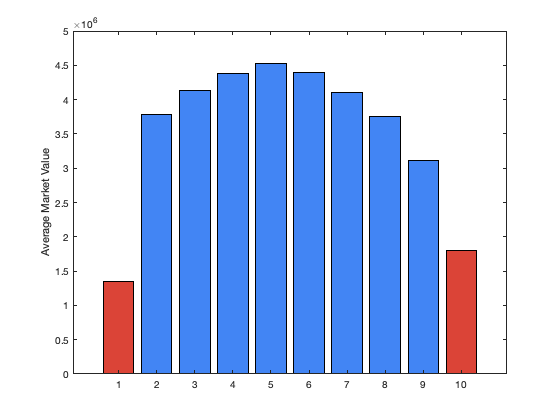

%Constructing average market-value for each portfolio
for i=61:408
    for j=1:10
    meq_port(i,j)=nanmean(meq(i,bab10fac.placement(i,:)==j),2); 
    end
end


figure;
p1=bar([1:10], nanmean(meq_port(61:end,:)), 'FaceColor',colorBrewer(1)); 
p1.FaceColor = 'flat';
ylabel('Average Market Value');
p1.CData(1,:) = colorBrewer(2);
p1.CData(10,:) = colorBrewer(2);

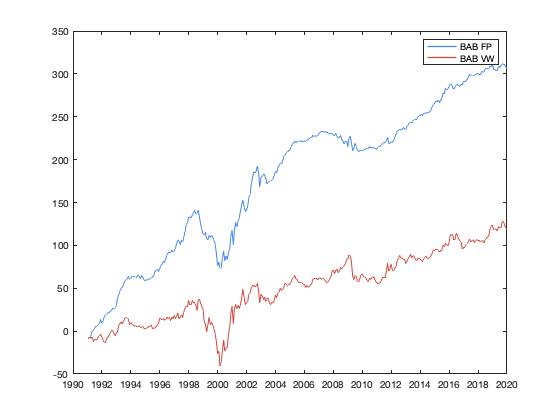



% Value weighted bab

w_h_vw=(abs(r-nanmean(r,2)).*((r-nanmean(r,2))>0).*meq)./nansum((abs(r-nanmean(r,2)).*((r-nanmean(r,2))>0).*meq),2); 
w_l_vw=(abs(r-nanmean(r,2)).*((r-nanmean(r,2))<=0).*meq)./nansum((abs(r-nanmean(r,2)).*((r-nanmean(r,2))<=0).*meq),2); 
beta_L_vw=nansum(beta.*w_l_vw,2); 
beta_H_vw=nansum(beta.*w_h_vw,2); 
beta_H_vw(beta_H_vw==0)=nan(); 
beta_L_vw(beta_L_vw==0)=nan(); 
r_L_vw=nansum(exret.*w_l_vw,2); 
r_H_vw=nansum(exret.*w_h_vw,2); 

BAB_factor2=1./beta_L_vw.*r_L_vw-1./beta_H_vw.*r_H_vw;

%Alphas and mean returns for new bab factor
regResults = nwRegress([BAB_factor2(61:end,:)],ones(348,1),0,6); 
table2(1,:)=regResults.bv(1,:); 
table2(2,:)=regResults.tbv(1,:); 
regResults = nwRegress([BAB_factor2(61:end,:)],ff(61:end,2),1,6); 
table2(3,:)=regResults.bv(1,:); 
table2(4,:)=regResults.tbv(1,:); 

regResults = nwRegress([BAB_factor2(61:end,:)],ff(61:end,2:4),1,6); 
table2(5,:)=regResults.bv(1,:); 
table2(6,:)=regResults.tbv(1,:); 


regResults = nwRegress([BAB_factor2(61:end,:)],ff5(61:end,:),1,6); 
table2(7,:)=regResults.bv(1,:); 
table2(8,:)=regResults.tbv(1,:); 

% Cumulative performance of vw bab vs original
figure; p1=plot(vDates(61:end,:),cumsum(BAB_factor(61:end,:))); 
hold on
p2=plot(vDates(61:end,:),cumsum(BAB_factor2(61:end,:))); 
datetick('x', 'yyyy')
p1(1).Color = colorBrewer(1);
p1(1).LineWidth = 1.2;
p2(1).Color = colorBrewer(2);
p2(1).LineWidth = 1.2;
legend('on', {'BAB FP', 'BAB VW'})




% Correctly estimated betas
beta_alt=nan(size(logReturns)); 
tic
M1 = movmean(logReturns(:,:).*logMkt(:,:),[250, 0],'omitnan');
M3 = movvar(logMkt(:,:),[250, 0],'omitnan');

beta_alt(1251:end,:)=M1(1251:end,:)./(M3(1251:end,:));
toc

Elapsed time is 5.886783 seconds.



nans=isnan(logReturns);
I=find((movsum(nans,[1250 0])>750));
beta_alt(I)=nan(); 

beta_alt=[beta_alt(month(vDatesDaily(2:end,:)) ~=month(vDatesDaily(1:end-1,:)),:);beta_alt(end,:)]; 
beta_alt         = beta_alt(:,permIdx);


figure; p1=plot(vDates(61:end,:), [nansum(meq(61:end,:).*beta_alt(61:end,:)./nansum(meq(61:end,:),2),2)])

p1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×348 double]
              YData: [1×348 double]
              ZData: [1×0 double]

  Show all properties


hold on
p2=plot(vDates(61:end,:), nansum(meq(61:end,:).*beta(61:end,:)./nansum(meq(61:end,:),2),2))

p2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×348 double]
              YData: [1×348 double]
              ZData: [1×0 double]

  Show all properties


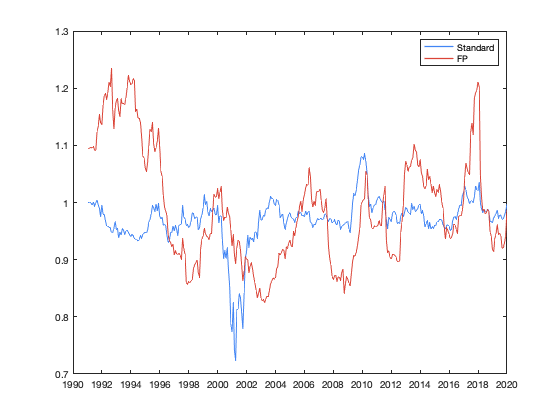

datetick('x', 'yyyy')
p1(1).Color = colorBrewer(1);
p2(1).Color = colorBrewer(2);
p1(1).LineWidth = 1.2;
p2(1).LineWidth = 1.2;
legend('on', {'Standard', 'FP'})




% Plot of Leverage and short position
figure; p1=plot(vDates(61:end,:), [1./beta_L(61:end)], 'Color', colorBrewer(1))

p1 =   Line with properties:

              Color: [0.2588 0.5216 0.9569]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×348 double]
              YData: [1×348 double]
              ZData: [1×0 double]

  Show all properties


hold on
p2=plot(vDates(61:end,:), [1./beta_H(61:end)], 'Color', colorBrewer(2))

p2 =   Line with properties:

              Color: [0.8588 0.2667 0.2157]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×348 double]
              YData: [1×348 double]
              ZData: [1×0 double]

  Show all properties


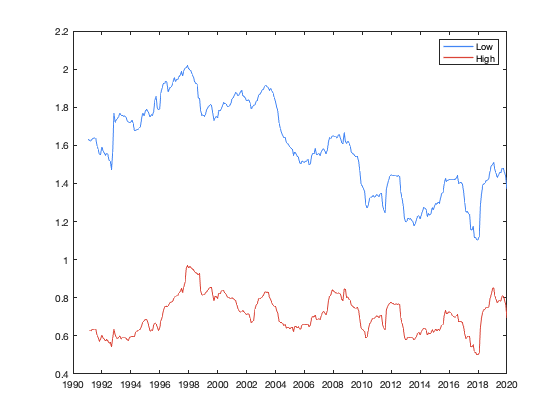

datetick('x', 'yyyy')
p1(1).Color = colorBrewer(1);
p1(1).LineWidth = 1.2;
p2(1).Color = colorBrewer(2);
p2(1).LineWidth = 1.2;
legend('on', {'Low', 'High'})



% Bali et. al measure for beta

out = bivariateSort(exret,FMAX,beta_alt,prctlVals,prctlVals,'Conditional','EW'); 

for i=1:10
    table4(i)=nanmean([out.returns(61:end,(i-1)*10+1)-out.returns(61:end,(i-1)*10+10)]); 
regResults = nwRegress([out.returns(61:end,(i-1)*10+1)-out.returns(61:end,(i-1)*10+10)],[ff5(61:end,:)],1,6); 
table5(1,i)=regResults.bv(1); 
table5(2,i)=regResults.tbv(1); 
end
table5

table5 =     0.3694    0.6055    0.4993    0.5414    0.5748    0.5758    0.7651    1.0631    1.4580    1.9951
    1.5739    2.9076    1.8615    1.8279    1.7511    1.5059    1.8686    2.2774    2.3198    3.2887
